# External ANC vs Internal ANC Analysis Code

Calculates the average difference between the External ANC (ExA) and Internal ANC (InA). Data from Arm 1 is used. 

### Cassady S. Olson 

Load data and set color parameters

clear 

% Load in data
% Add data folder to path
addpath("data\")
% arm 1 data
load("Arm1_Measurement.mat")


% figure color parameters
blue = [0,0,255/255]; 
orange = [255/255,165/255,0];

% Proximal - distal tag
posID = [1,2,3];
% Number of points along proximal - distal axis
numPos = 3;
ExIn = 2;
posLabel = {'Proximal', 'Intermediate', 'Distal'};

## ExA vs InA Segment Width 

Calculate the average and SEM of the segments subdivided by those on the ExA vs InA.

% arm 1 segments
segWidth = Measurement.segWidth; 

avgWidthTotal = [];
semWidthTotal = []; 
for n = 1:numPos
    for m = 1:ExIn
        both = find(segWidth(:, 5) == m & segWidth(:, 2) == n);
        avgWidthTotal(n, m) = mean(segWidth(both, 1));
        semWidthTotal(n, m) = std(segWidth(both, 1))./sqrt(length(segWidth(both,1)));
    end
end

Run stats to compute significance down the proximal-distal axis and between ExA and InA

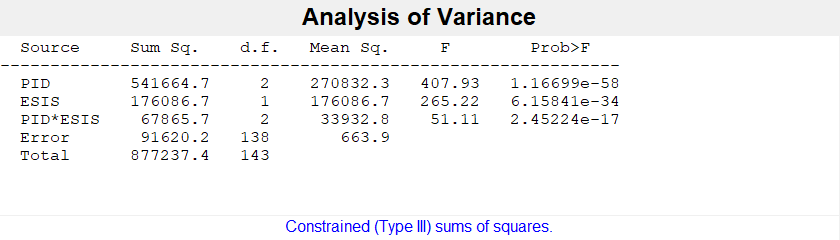

[p1, table1, stats1] = anovan(segWidth(:,1), {segWidth(:,2), segWidth(:,5)},'model', 'interaction','varnames', {'PID', 'ESIS'});

Run post hoc

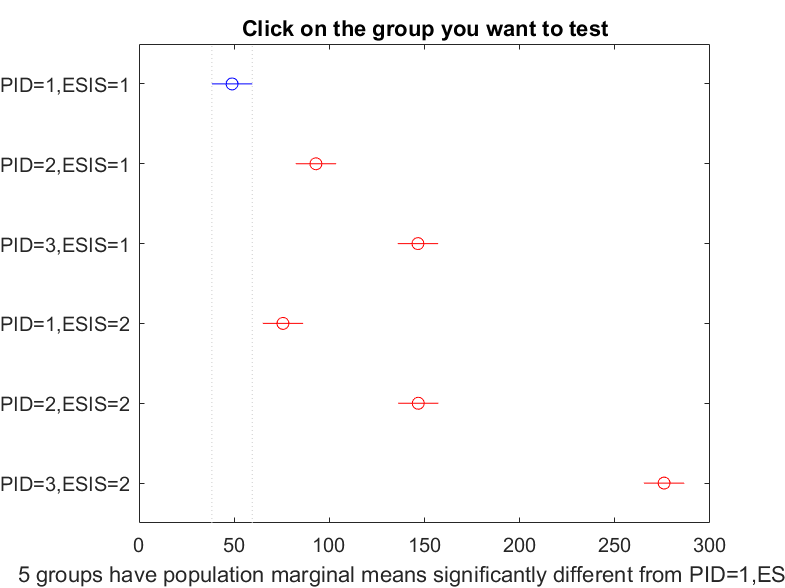

[c1, ~, h1] = multcompare(stats1, "Dimension",[1,2]);

Generate plot with significance stars 

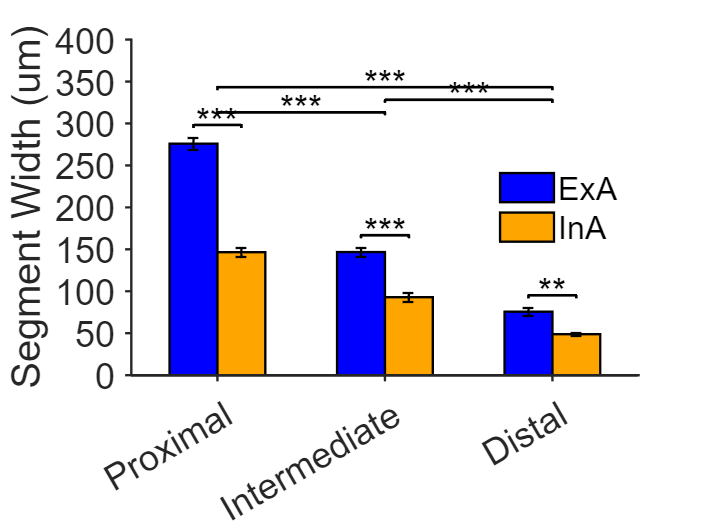

clear z

% Plot with stars
figure, 
b = bar(flip(flip(avgWidthTotal,2)), 'LineWidth', 1.3, 'BarWidth',1);
hold on 

[ngroups,nbars] = size(avgWidthTotal);

% Get the x coordinate of the bars
for i = 1:nbars
    z(i,:) = b(i).XEndPoints;
end
z = z';

% add errorbar
er = errorbar(z,flip(flip(avgWidthTotal,2)), flip(flip(semWidthTotal,2)), 'LineStyle', 'none', 'Color', 'k', 'LineWidth', 1.3);   

% Use sigstar to add stars
% select significance values for relavent groups 
comp = [5, 6; 4, 5; 4, 6; 3, 6; 2, 5; 1, 4];
for get = 1:length(comp)
    indx = find(comp(get, 1) == c1(:, 1) & comp(get, 2) == c1(:,2));
    pVal(get) = c1(indx, end); 
end

% array of comparision groups 
groups = {[1,2], [2,3], [1, 3], z(1,:), z(2, :), z(3, :)}; 

% add stars
a = sigstar(groups, pVal);
set(a(:,2),'FontSize',20)


% Set plot parameters 
b(1,1).FaceColor = [0,0,255/255];
b(1, 2).FaceColor = [255/255,165/255,0];

legend('ExA', 'InA', 'Location', 'east', 'TextColor', 'k')
legend('boxoff')
xticklabels((posLabel))
ylabel('Segment Width (um)')
axis normal
ax = gca; 
ax.FontSize = 20;
ax.Box = 'off';
ax.TickDir = 'out';
ax.LineWidth = 1.3;
xticks([1,2,3])
ylim([0,400])
yticks([0:50:400])

## External ANC vs Internal ANC Cell density 

Calculate the average and SEM of the cell density from segments subdivided by ExA and InA. 

% arm 1 desnity 
density = Measurement.density;

avgDens = [];
semDens = [];

for n = 1:numPos
    for m = 1:ExIn
        both = find(density(:, 4) == n & density(:, 7) == m);
        avgDens(n, m) = mean(density(both, 3));
        semDens(n, m) = std(density(both, 3))./sqrt(length(density(both,3)));
    end
end


Run stats to compute significance down the proximal-distal axis and between ExA and InA

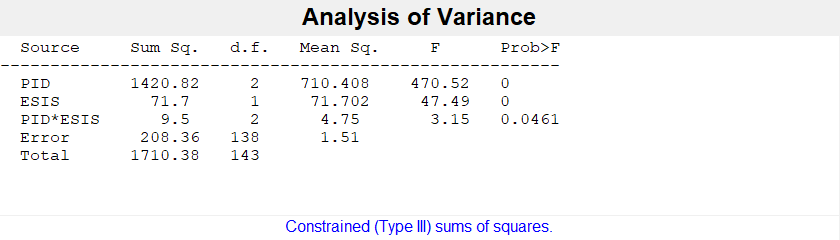

[p2, table2, stats2] = anovan(density(:,3), {density(:,4), density(:,7)}, 'model', 'interaction', 'varnames', {'PID', 'ESIS'});

Run post hoc

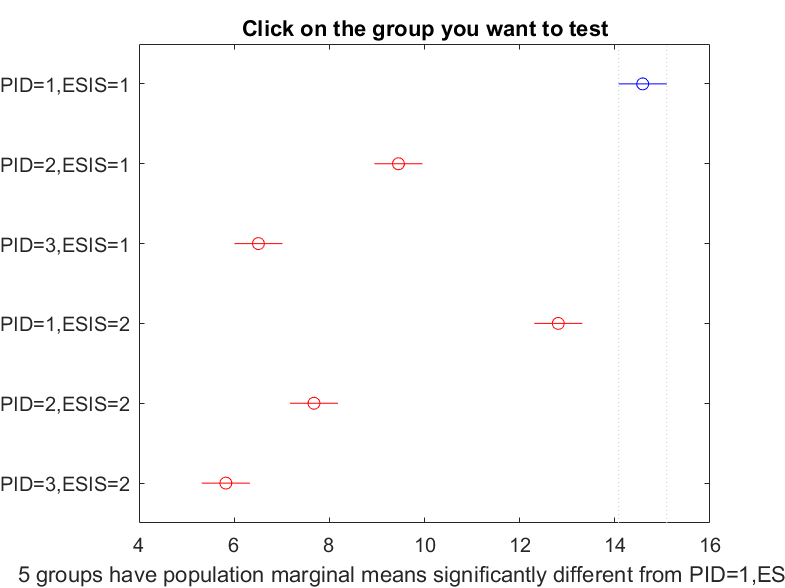

c2 = multcompare(stats2, "Dimension",[1,2]);

Generate plot with significance stars

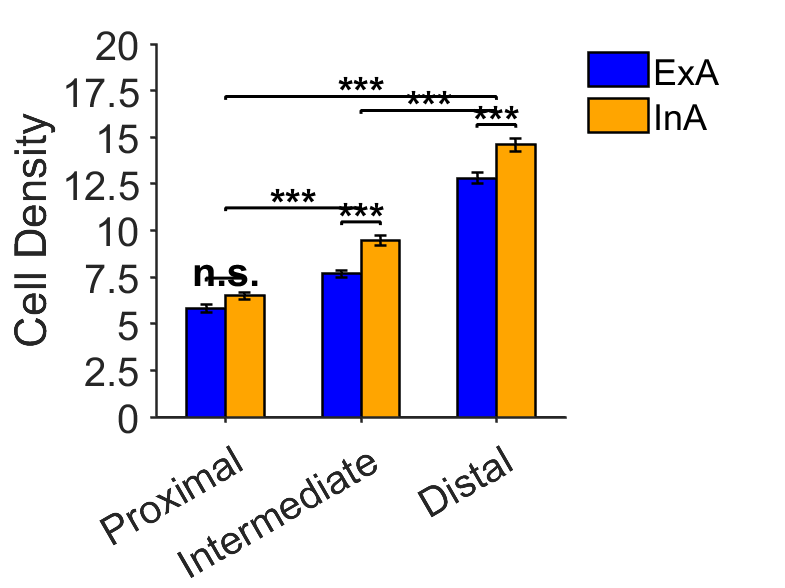

clear w 

% Plot with stars
figure,
b = bar(flip(flip(avgDens,2)), 'LineWidth', 1.3, 'BarWidth',1);
hold on 
[ngroups,nbars] = size(avgDens);
% Get the x coordinate of the bars
w = nan(nbars, ngroups);
for i = 1:nbars
    w(i,:) = b(i).XEndPoints;
end
w = w'; 

% add errorbar 
er = errorbar(w,flip(flip(avgDens,2)), flip(flip(semDens,2)), 'LineStyle','none', 'Color', 'k', 'LineWidth', 1.3);  

% Use sigstar to add stars
% select significance values for relavent groups 
for get = 1:length(comp)
    indx = find(comp(get, 1) == c2(:, 1) & comp(get, 2) == c2(:,2));
    pVal1(get) = c2(indx, end); 
end
% array of comparision groups 
groups = {[1,2], [2,3], [1, 3], w(1,:), w(2, :), w(3, :)}; 
% Add stars
a1 = sigstar(groups, pVal1);
set(a1(:,2),'FontSize',20, 'FontWeight', 'bold')
set(a1, 'Color', 'k')

% Set plot parameters 
b(1, 1).FaceColor = blue;
b(1, 2).FaceColor = orange;
legend('ExA', 'InA', 'Location','northeastoutside','TextColor', 'k')
legend('boxoff')
xticklabels((posLabel))
ylabel('Cell Density')
ylim([0,20])
yticks(0:2.5:20)
axis normal
ax = gca; 
ax.Box = 'off';
ax.TickDir = 'out';
ax.LineWidth = 1.3;
xticks([1,2,3])
ax.FontSize = 20;